## Problem 1.2-1

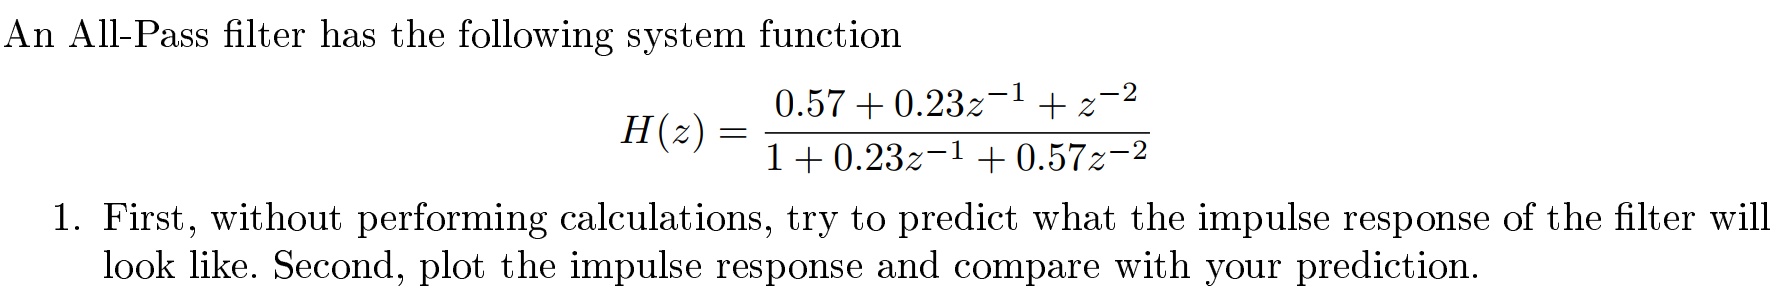

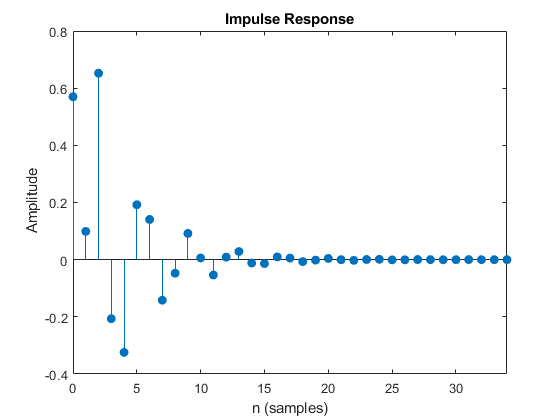

b = [0.57, 0.23, 1];
a = [1, 0.23, 0.57];
impz(b, a);

## Problem 1.2-2

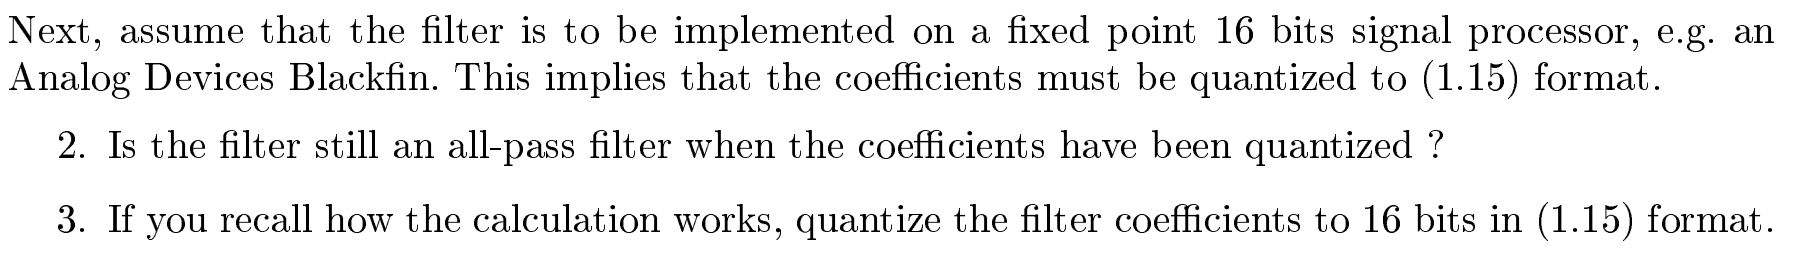

b = [0.57, 0.23, 1];
a = [1, 0.23, 0.57];
[h, t] = impz(b, a);

bits = 16;
maxVal = (2^(bits-1))-1;
minVal = (2^(bits-1));


Normalise the inpulse response between -1 and +1 assuming that the maximum value is positive.

normalisedH = h./max(h);

Quantise the positive values 

quantisedH = normalisedH.* maxVal;

Find the index of negative values:

negIndices = find(normalisedH < 0);
quantisedH(negIndices) = normalisedH(negIndices).* minVal;


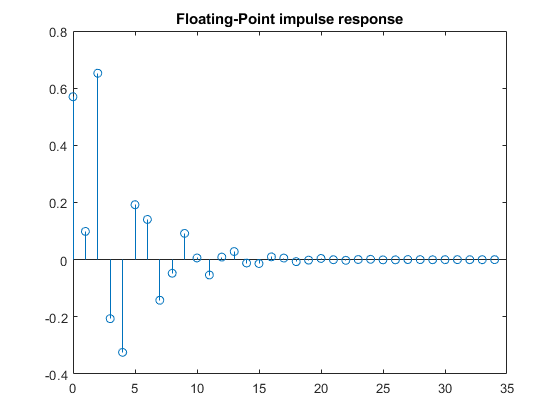

stem([0:34], h);
title('Floating-Point impulse response');

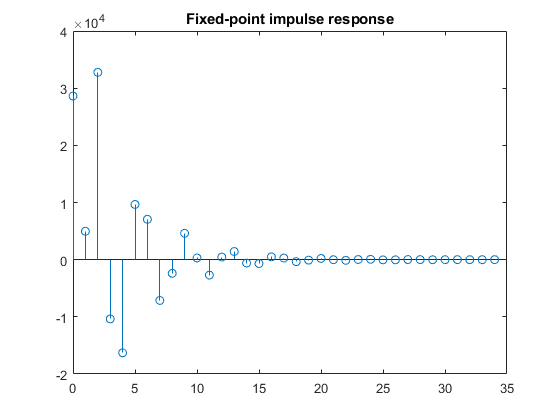

stem([0:34], quantisedH);
title('Fixed-point impulse response');